## Bergman Minimal Model

In 1979 Bergman’s minimal model (BMM) as a dynamic model of plasma glucose concentration was built as a powerful tool to estimate insulin sensitivity based on IVGTT. Let's show how to easily use it in 5 simple steps.

### 1. Preprocess the data from the IVGTT

[t, g, i] = importfile('IVGTT_AP.csv');

### 2. Plot data from the IVGTT

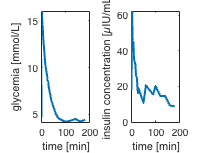

figure
subplot(121); plot(t, g, '-','Linewidth',2); hold on
xlabel('time [min]'); ylabel('glycemia [mmol/L]')
subplot(122); plot(t, i, '-','Linewidth',2)
xlabel('time [min]'); ylabel('insulin concentration [µIU/mL]')

### 3. Compile a simulation scheme of BMM

We've got you covered

open_system('bmm_sim.slx')

### 4. Implement a identification method of Bergman model parameters

Initialize optimized variables

p2 = 1e-4;
Si = 10e-1;
Sg = 3.6e-2;
G0 = 16;
X0 = 0;
Ib = i(1);
Gb = g(1);

x0 = [p2 Si Sg G0 X0 Ib Gb];

Initialize input

input_sim.time = t;
input_sim.signals.values = i;
input_sim.signals.dimensions = 1;

Set optimization options

opts = optimset('Display', 'iter', 'MaxIter', 250);

Run identification

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          135.637         
     1            8          119.872         initial simplex
     2           10          104.032         expand
     3           11          104.032         reflect
     4           13          88.5688         expand
     5           14          88.5688         reflect
     6           16          67.5015         expand
     7           17          67.5015         reflect
     8           18          67.5015         reflect
     9           20          45.7116         expand
    10           21          45.7116         reflect
    11           22          45.7116         reflect
    12           23          45.7116         reflect
    13           24          45.7116         reflect
    14           26          43.4897         reflect
    15           27          43.4897         reflect
    16           28          43.4897         reflect
    17           29          43.4897         

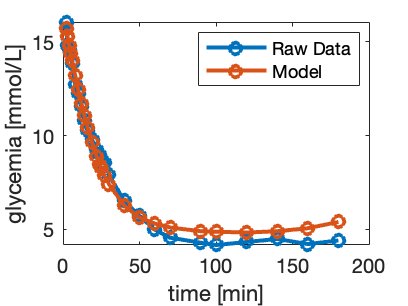

    50           81          4.97046         contract inside
 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 4.970459 



x_opt =     0.0001    0.3055    0.0402   16.6937    0.0012   17.6262    5.9965


fval = 4.9705

exitflag = 0

output = struct with fields:
    iterations: 50
     funcCount: 81
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Exiting: Maximum number of iterations has been exceeded↵         - increase MaxIter option.↵         Current function value: 4.970459 ↵'


[x_opt, fval, exitflag, output] = ...
    fminsearch(@objectiveFcn, x0, opts, g(2:end), t(2:end), 1)

### 5. Evaluation of results

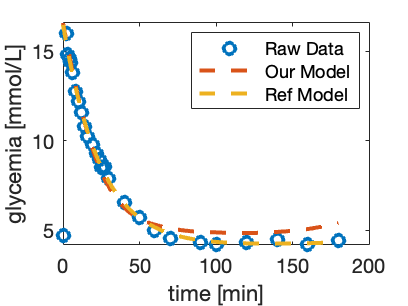

figure
plot(t, g, 'o','Linewidth',2); hold on

out = sim('bmm_sim.slx');
plot(out.OutData(:,1),out.OutData(:,2), '--','Linewidth',2); hold on

p2 = 1.0744e-4; Si = 0.0113; Sg = 0.0394;
G0 = 16.4964; X0 = 0.0009;
Ib = 34.2943; Gb = 4.0957;

set_param('bmm_sim/BMM/Gain_Sg', 'Gain', num2str(Sg));
set_param('bmm_sim/BMM/Gain_Sip2', 'Gain', num2str(Si*p2))
set_param('bmm_sim/BMM/Gain_p2', 'Gain', num2str(p2))
set_param('bmm_sim/BMM/Integrator_G', ...
          'InitialCondition', num2str(G0))
set_param('bmm_sim/BMM/Integrator_X', ...
          'InitialCondition', num2str(X0))
set_param('bmm_sim/Ib', 'Value', num2str(Ib))
set_param('bmm_sim/Gb', 'Value', num2str(Gb))

out_ref = sim('bmm_sim.slx');
plot(out_ref.OutData(:,1), ...
     out_ref.OutData(:,2), ...
     '--','Linewidth',2); hold on

xlabel('time [min]'); ylabel('glycemia [mmol/L]')
legend('Raw Data', 'Our Model', 'Ref Model')